clc; clear;
%--------------Task_1---------------
global r0 r1 r2 r3 r4 r5 ub

r0 = 1000; r1 = 9000; r2 = r1; r3 = r1; r4 = r1; r5 = r1;
c1 = 1e-6; c2 = 2e-6; c3 =3e-6; ub = 6;

u0 = [1e-36; ub*r1/(r1+r2); ub*r1/(r1+r2); ub; 1e-36];
G = [-c1 c1 0 0 0; c1 -c1 0 0 0; 0 0 -c2 0 0; 0 0 0 -c3 c3; 0 0 0 c3 -c3];

[mesh_1,u_1] = DiffAlgROS(0, 0.3, 1/5000, G, 1/2, u0)

mesh_1 =          0    0.0002    0.0004    0.0006    0.0008    0.0010    0.0012    0.0014    0.0016    0.0018    0.0020    0.0022    0.0024    0.0026    0.0028    0.0030    0.0032    0.0034    0.0036    0.0038    0.0040    0.0042    0.0044    0.0046    0.0048    0.0050    0.0052    0.0054    0.0056    0.0058    0.0060    0.0062    0.0064    0.0066    0.0068    0.0070    0.0072    0.0074    0.0076    0.0078    0.0080    0.0082    0.0084    0.0086    0.0088    0.0090    0.0092    0.0094    0.0096    0.0098


u_1 =     0.0000    0.0103    0.0204    0.0300    0.0383    0.0463    0.0547    0.0621    0.0690    0.0744    0.0791    0.0822    0.0843    0.0848    0.0843    0.0822    0.0791    0.0744    0.0690    0.0621    0.0546    0.0459    0.0368    0.0268    0.0168    0.0062   -0.0042   -0.0149   -0.0249   -0.0349   -0.0440   -0.0527   -0.0603   -0.0672   -0.0727   -0.0774   -0.0806   -0.0828   -0.0833   -0.0829   -0.0808   -0.0778   -0.0732   -0.0678   -0.0609   -0.0535   -0.0448   -0.0358   -0.0258   -0.0158
    3.0000    3.0101    3.0195    3.0279    3.0345    3.0403    3.0461    3.0506    3.0544    3.0567    3.0581    3.0579    3.0569    3.0543    3.0509    3.0460    3.0404    3.0336    3.0263    3.0179    3.0093    3.0000    2.9907    2.9809    2.9715    2.9619    2.9529    2.9441    2.9363    2.9288    2.9226    2.9169    2.9127    2.9091    2.9072    2.9060    2.9065    2.9077    2.9106    2.9142    2.9194    2.9251    2.9322    2.9397    2.9482    2.9570    2.9666    2.9760    2.9860   

[mesh_2,u_2] = DiffAlgROS(0, 0.3, 1/5000, G, (1+j)/2, u0)

mesh_2 =          0    0.0002    0.0004    0.0006    0.0008    0.0010    0.0012    0.0014    0.0016    0.0018    0.0020    0.0022    0.0024    0.0026    0.0028    0.0030    0.0032    0.0034    0.0036    0.0038    0.0040    0.0042    0.0044    0.0046    0.0048    0.0050    0.0052    0.0054    0.0056    0.0058    0.0060    0.0062    0.0064    0.0066    0.0068    0.0070    0.0072    0.0074    0.0076    0.0078    0.0080    0.0082    0.0084    0.0086    0.0088    0.0090    0.0092    0.0094    0.0096    0.0098


u_2 =     0.0000    0.0052    0.0154    0.0252    0.0341    0.0425    0.0510    0.0589    0.0661    0.0722    0.0772    0.0810    0.0836    0.0849    0.0848    0.0834    0.0808    0.0768    0.0717    0.0655    0.0582    0.0501    0.0411    0.0316    0.0215    0.0111    0.0006   -0.0100   -0.0203   -0.0304   -0.0399   -0.0489   -0.0570   -0.0642   -0.0704   -0.0755   -0.0794   -0.0821   -0.0834   -0.0834   -0.0821   -0.0794   -0.0756   -0.0705   -0.0643   -0.0570   -0.0489   -0.0400   -0.0305   -0.0205
    3.0000    3.0049    3.0145    3.0232    3.0304    3.0365    3.0423    3.0474    3.0515    3.0544    3.0562    3.0568    3.0562    3.0543    3.0514    3.0473    3.0421    3.0360    3.0290    3.0213    3.0130    3.0042    2.9950    2.9856    2.9762    2.9668    2.9577    2.9490    2.9408    2.9333    2.9266    2.9208    2.9159    2.9121    2.9094    2.9079    2.9076    2.9085    2.9105    2.9138    2.9181    2.9235    2.9298    2.9369    2.9449    2.9534    2.9624    2.9718    2.9814   

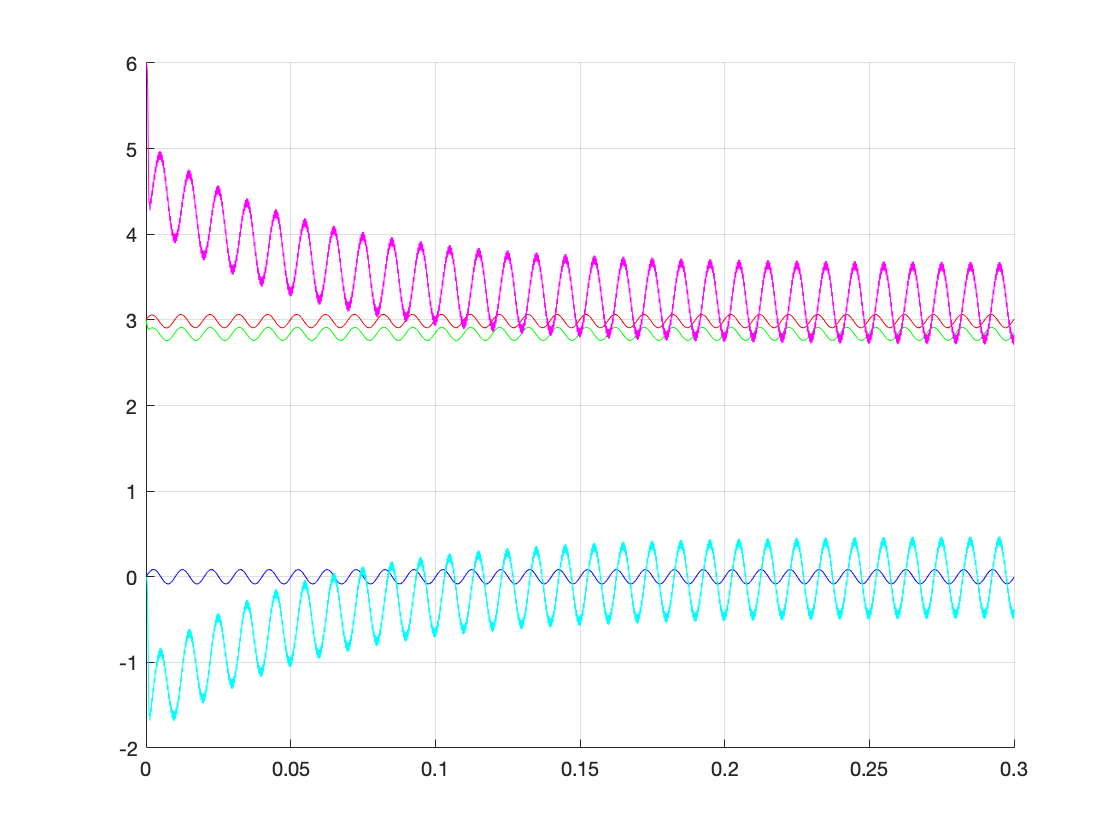


figure(1);
hold on; grid on;

plot(mesh_1,u_1(1,:),'b')
plot(mesh_1,u_1(2,:),'r')
plot(mesh_1,u_1(3,:),'g')
plot(mesh_1,u_1(4,:),'m')
plot(mesh_1,u_1(5,:),'c')

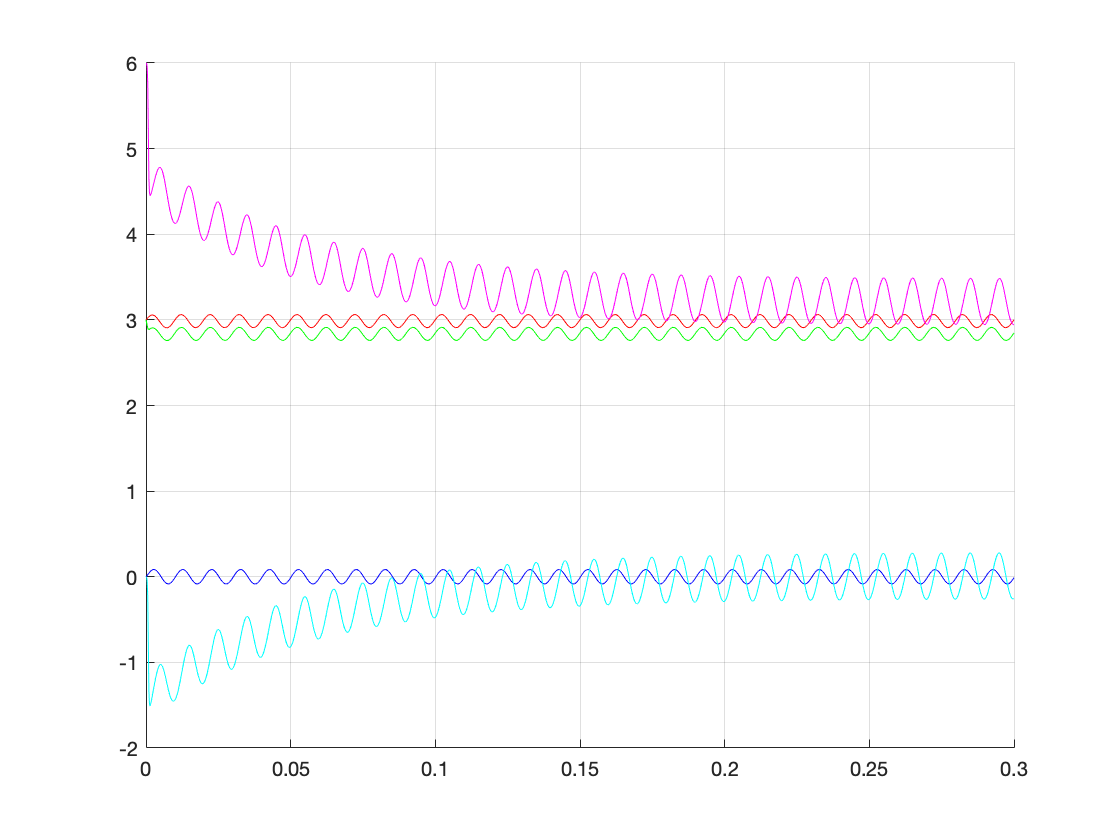


figure(2);
hold on; grid on;

plot(mesh_2,u_2(1,:),'b')
plot(mesh_2,u_2(2,:),'r')
plot(mesh_2,u_2(3,:),'g')
plot(mesh_2,u_2(4,:),'m')
plot(mesh_2,u_2(5,:),'c')

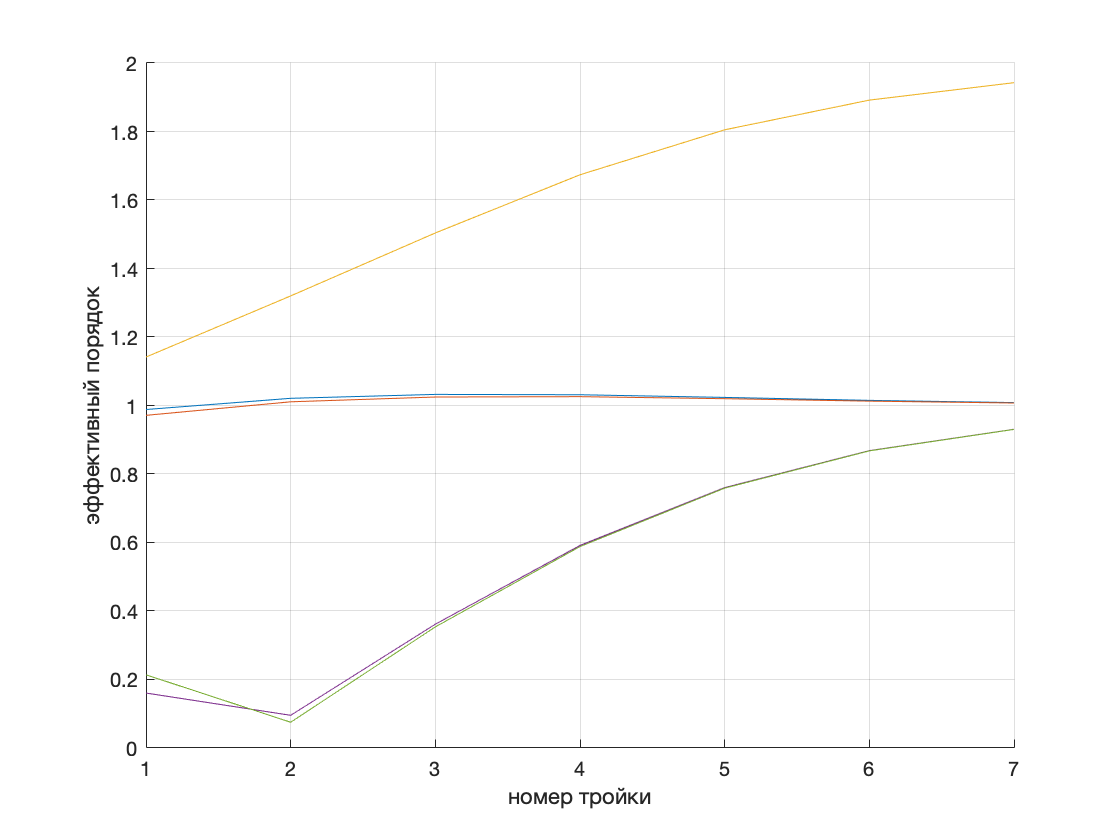


%--------------Task_2---------------Part_1---------------
tau = [1/1000 1/2000 1/4000 1/8000 1/16000 1/32000 1/64000 1/128000 1/256000];
LastP = zeros(length(u0), length(tau));

for k = 1:1:size(tau, 2)
    [t,U] = DiffAlgROS(0, 0.01, tau(k), G, (1+j)/2, u0);
    LastP(:,k) = U(:,end);
end

figure(3);
hold on; grid on;
xlabel('номер тройки'); ylabel('эффективный порядок')

for i = 1:1:length(u0)
    S = LastP(i,:);
    for  r =1:1:size(tau,2) - 2
        p(i,r)  = abs(log2((S(r+2) - S(r+1))/(S(r+1) -S(r))));
    end
    plot(1:size(tau,2) - 2,p(i,:)) 
end

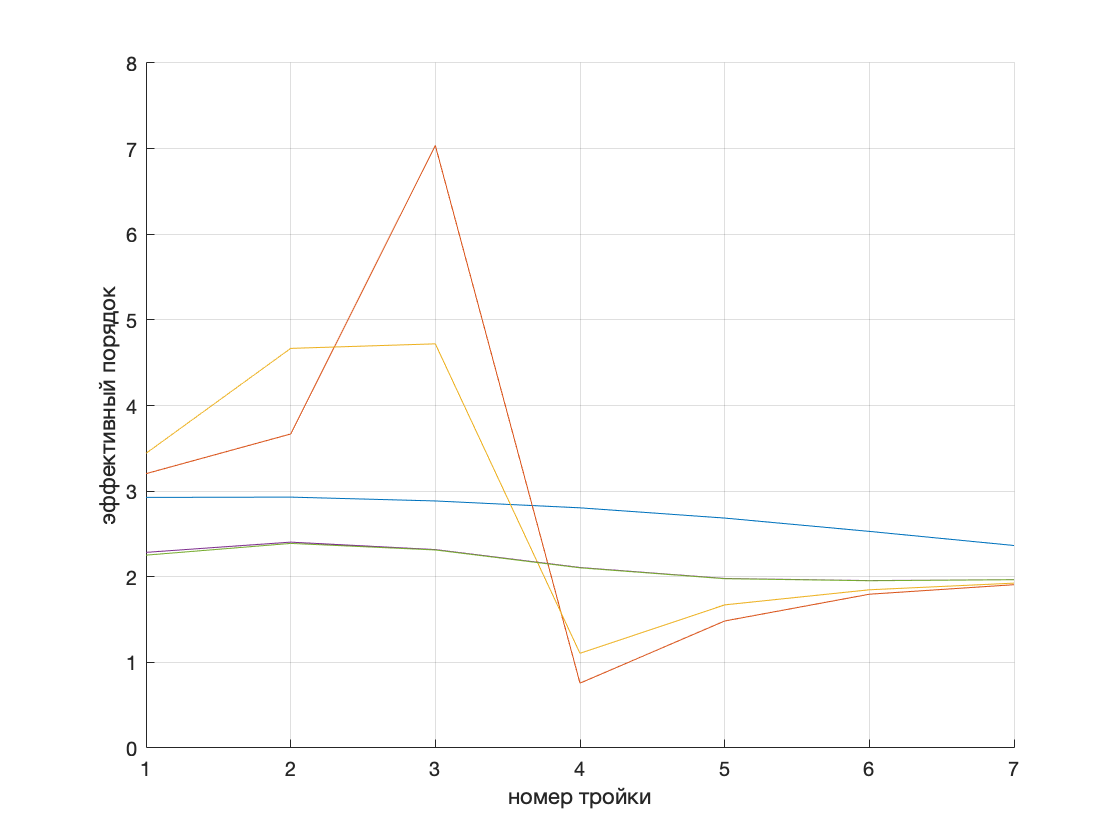


%--------------Task_2---------------Part_2---------------
u0 = [1e-36; ub*r1/(r1+r2); ub*r1/(r1+r2); ub; 1e-36; 1e-36];
G = [-c1 c1 0 0 0 0; 
     c1 -c1 0 0 0 0; 
     0  0 -c2 0 0 0; 
     0 0 0 -c3 c3 0; 
     0 0 0 c3 -c3 0;
     0 0 0  0   0 1];

tau = [1/1000 1/2000 1/4000 1/8000 1/16000 1/32000 1/64000 1/128000 1/256000];
LastP = zeros(length(u0), length(tau));

for k = 1:1:size(tau, 2)
    [t,U] = DiffAlgROSAuto(0, 0.01, tau(k), G, (1+j)/2, u0);
    LastP(:,k) = U(:,end);
end

figure(4);
hold on; grid on;
xlabel('номер тройки'); ylabel('эффективный порядок')

for i = 1:1:length(u0)
    S = LastP(i,:);
    for  r =1:1:size(tau,2) - 2
        p(i,r)  = abs(log2((S(r+2)-S(r+1))./(S(r+1)-S(r))));
    end
plot(1:size(tau,2) - 2,p(i,:)) 
end